# **Clasificación de señales EMG usando el Classification Learner Toolbox de Matlab**

Estudiantes:

- **Luis Enrique Santamaria Candelario**

- **Abel Francisco Gomez Campuzano**

- **Dyllan Ricardo Bastidas Palacios**

Características del experimentos:

- 1. Sin presion

- 2. Con presion

- 3. Presion 2 veces

- 4. Presion 3 veces

Características del hardware:

- Frecuencia de muestreo: 100Hz

- Sensor MYO Ware

Referencias:

- **Funciones de Matlab: **[**https://github.com/vasanza/Matlab_Code**](https://github.com/vasanza/Matlab_Code)

- **Ejemplo de clasificacón EMG: **[**https://vasanza.blogspot.com/2020/01/alphabet-letters-recognition-with.html**](https://vasanza.blogspot.com/2020/01/alphabet-letters-recognition-with.html)

- **Ejemplo de clasificacón EEG: **[**https://vasanza.blogspot.com/2020/01/eeg-signal-classification-with-machine.html**](https://vasanza.blogspot.com/2020/01/eeg-signal-classification-with-machine.html)

Notas para el uso:

- Se recomienda organizar los datos en la carpeta "data" y las funciones en la carpeta "src".

- Para ejecutar el codigo principal "main.mlx", poner el current folder en la misma ubicación.

- **En el siguiente enlace se puede revisar como fue desarrollado el presente codigo: **[**https://youtu.be/UI7Oa1sXEeY**](https://youtu.be/UI7Oa1sXEeY)

# 1- Load Raw Data

clear;clc;%clear all
%Prepare the raw dataset
addpath(genpath('./src'))%functions folders
datapath = fullfile('./data/');%data folder
folderNames=FindFolders(datapath);
allData=[];
for j=1:length(folderNames)
    path1=fullfile(datapath,folderNames(j).name);
    filenames = FindCSV(path1);%List All CSV files
    for i=1:length(filenames)% Through all files
        data=readtable(fullfile(path1,filenames(i).name));%Select i CSV file
        %The first 3 columns are deleted: topic, server date, esp32 date, and esp32 date.
        %data=[data(:,2) data(:,5:end)];
        dataNew=table2array(data);% Array Double
        dataNew(isnan(dataNew)) = 0;%Remove NAN numbers
        Label=str2double(filenames(i).name(4));
        %allData=[allData;[rms(dataNew) Label]];%feauture
        allData=[allData;[max(dataNew) min(dataNew) Label]];
    end
end


# 1.2- Grafica de datos

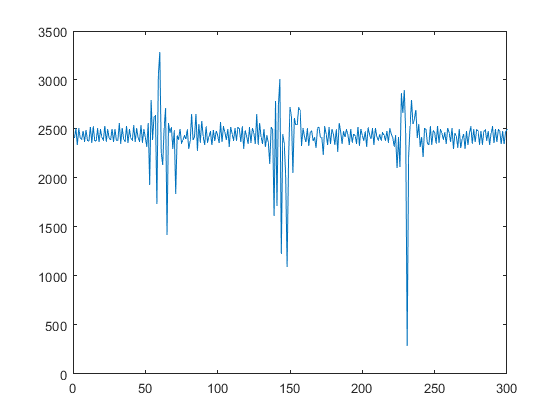

%Plot de las señales del ultimo archivo (tarea 4)
plot(dataNew);

%legend('Ax','Ay','Az','Gx','Gy','Gz');
%title('Tarea: Cómo estás?');
%xlabel('Samples');
%ylabel('Valores en bits');

# 2- Classification

%Para una data binaria
%index1 = find(allData(:,2)==1);%Incluir esta clase en la clasificación
%index2 = find(allData(:,2)==4);%Incluir esta clase en la clasificación
%BinaryData=[allData(index1,:);allData(index2,:)];
%[RandomData,IndexRows] = fRandomize_DataRows(BinaryData);
%[Training, Validation] = fsplit_data(RandomData, 0.7);
%clear data dataNew;

%%4tareas
%[RandomData,IndexRows] = fRandomize_DataRows(allData);
%[Training, Validation] = fsplit_data(RandomData, 0.7);%70% para Training y 30% para validation
%

%Para una data terneria
index1 = find(allData(:,3)==1);%Incluir esta clase en la clasificación
index2 = find(allData(:,3)==2);%Incluir esta clase en la clasificación
index3 = find(allData(:,3)==4);%Incluir esta clase en la clasificación
TernaryData=[allData(index1,:);allData(index2,:);allData(index3,:)];
[RandomData,IndexRows] = fRandomize_DataRows(TernaryData);
[Training, Validation] = fsplit_data(RandomData, 0.7);



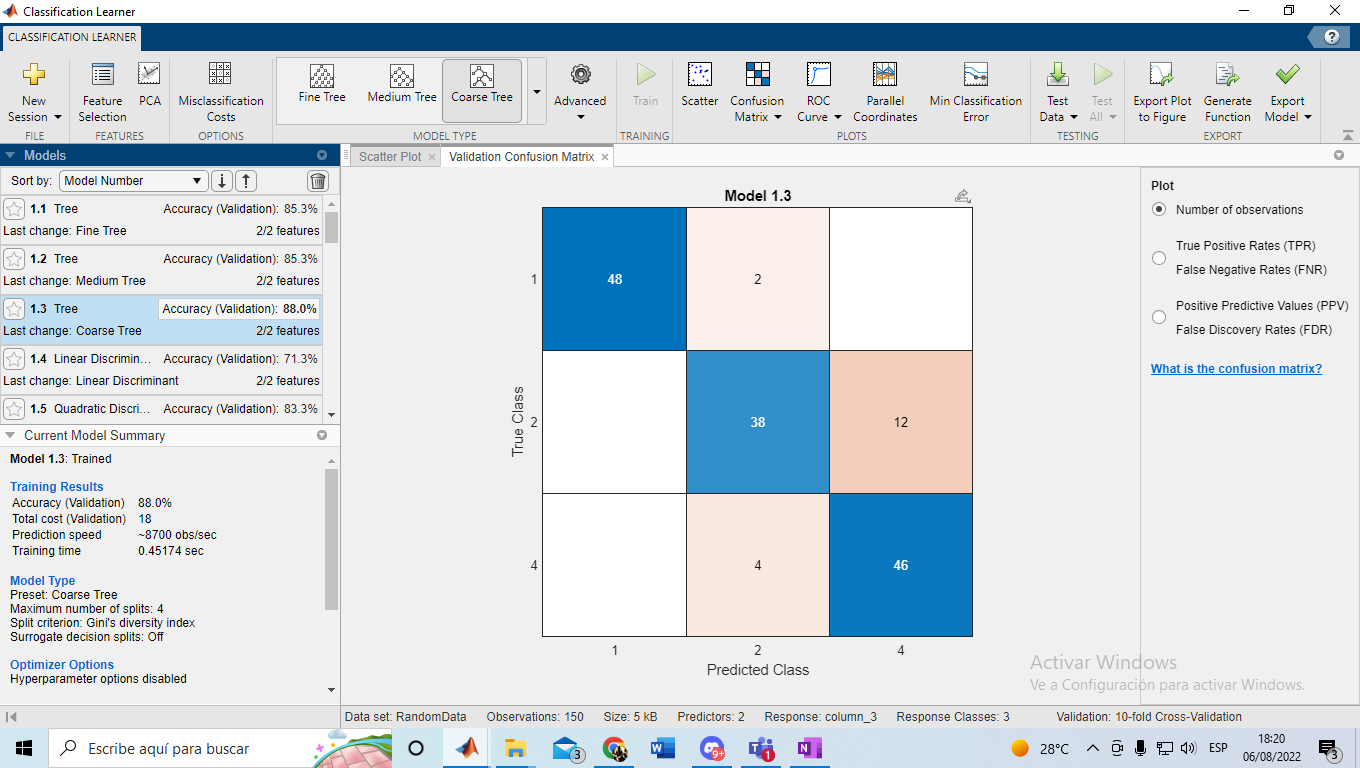

# 3- Validation

[trainedClassifier, validationAccuracy]=trainClassifierCoarserTree(Training);

yfit = trainedClassifier.predictFcn(Validation(:,1:2));
TrueClass=Validation(:,3);
compare=[yfit TrueClass];

# 4- ThingSpeak

https://github.com/vasanza/Matlab_Code/blob/main/LinearRegression_ThingSpeak.m

%tarea